# Minimum Actuation Time - TASK 1/3

### Robot characteristic

%Definizione delle caratteristiche del robot
clc 
clear all
close all
set(0, 'DefaultFigureRenderer', 'painters');
load_robot_specs

P1 = [0.25 0.6 h-0.5];
P2 = [-0.4 1.1 h-0.1];
P3 = [-0.25 1.1 h-0.7];

### 1) Trajectory Planning

dS = norm(P3-P1);
% Alfa
[T_alfa,l1_alfa,l3_alfa] = minActuationTime(acc_limits(1,1),acc_limits(1,2),vel_limits(1,1),dS);
% Beta
[T_beta,l1_beta,l3_beta] = minActuationTime(acc_limits(1,3),acc_limits(1,4),vel_limits(1,3),dS);
% Rho
[T_rho,l1_rho,l3_rho] = minActuationTime(acc_limits(1,5),acc_limits(1,6),vel_limits(1,5),dS);

switch min([T_alfa T_beta T_rho])
    case T_alfa
        T=T_alfa; lamda1=l1_alfa; lamda3=l3_alfa;
    case T_beta
        T=T_beta; lamda1=l1_beta; lamda3=l3_beta;
    case T_rho
        T=T_rho;  lamda1=l1_rho;  lamda3=l3_rho;
end

n = 100;
dT = T/(n-1);

### 1) Kinematics - gripper coordinates 

#### 
$$\dot{Q} = J\dot{S}$$


Calculate the trajectory


$$\dot{J}_s \dot{S} + J_s \ddot{S} + \dot{J} _q \dot{Q}+J_q\ddot{Q}=0$$


Q_1 = inverse_kinematics(P3,L,[130*pi/180 50*pi/180]);
Q_2 = inverse_kinematics(P1,L,[130*pi/180 50*pi/180]);

dQ = Q_2 - Q_1;

for i = 1:n
    t = (i-1)*dT;
    tt(i) = t;
    [q(i,:) qp(i,:) qpp(i,:)] = tretratti(t,T,Q_1,dQ,lamda1,lamda3);
    
    if i==1
        guess = [0 80];
    else
        guess = s(i-1,:);
    end
    
    s(i,:) = direct_kinematics(q(i,:),L,guess);
    [J, J_s, J_q] = Jacobian(s(i,1:2),q(i,1:2),L);
    v(i,:) = inv(J)*qp(i,1:2)';
    a(i,:) = -inv(J_s)*(Jp_s(q(i,1:2),qp(i,1:2),v(i,:),L)*v(i,:)'+Jp_q(s(i,:),q(i,1:2),qp(i,1:2),v(i,:),L)*qp(i,1:2)'+J_q*qpp(i,1:2)');
    
end


### 2D Plot

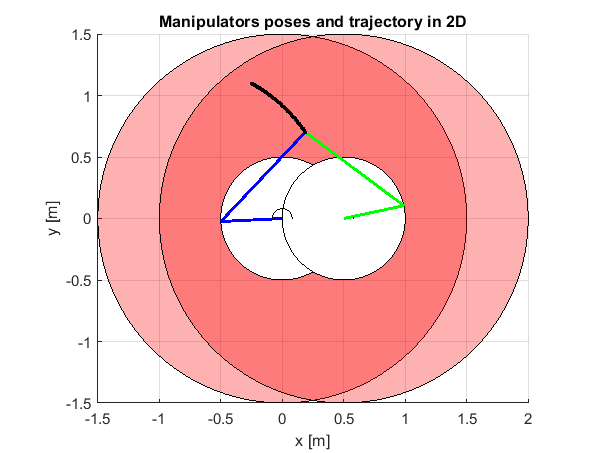

close all

figure(1)
% Plot workspace
center_x = 0; center_y = 0; radius = l1+l2; th = 0:pi/50:2*pi; % radians
coordinates_x = radius*cos(th) + center_x; coordinates_y = radius * sin(th) + center_y;
% Plot the circle
patch(coordinates_x,coordinates_y,'red')
axis square tight 
alpha(0.3)
center_x = l0; center_y = 0; radius = l1+l2; th = 0:pi/50:2*pi; % radians
coordinates_x = radius * cos(th) + center_x; coordinates_y = radius * sin(th) + center_y;
% Plot the circle
patch(coordinates_x,coordinates_y,'red')
axis square tight 
alpha(0.3)

center_x = 0; center_y = 0; radius = l2-l1; th = 0:pi/50:2*pi; % radians
coordinates_x = radius * cos(th) + center_x; coordinates_y = radius * sin(th) + center_y;
patch(coordinates_x,coordinates_y,'white')

center_x = l0; center_y = 0; radius = l2-l1; th = 0:pi/50:2*pi; % radians
coordinates_x = radius * cos(th) + center_x; coordinates_y = radius * sin(th) + center_y;
patch(coordinates_x,coordinates_y,'white')
axis equal
grid on

for i=1:length(s)
    % Print
    [config1, theta(i)] = plot2D_1st(q(i,:),L,1,s(i,1),s(i,2));
    [config2, gamma(i)] = plot2D_2nd(q(i,:),L,1,s(i,1),s(i,2));
    plot(s(i,1),s(i,2),'.-black')
    % Plot the angle arc
    h1 = plotAngleArc([0,0],0.08,[0,q(i,1)],'k-',1); %alfa
    h2 = plotAngleArc([l0,0],0.08,[0,q(i,2)],'k-',1); %beta
    
    pause(dT)
    if i==length(s)
        break
    end
    delete(config1); delete(config2); delete(h1); delete(h2);
    hold off
    title('Manipulators poses and trajectory in 2D');
    xlabel('x [m]')
    ylabel('y [m]')
end

### 3D Plot

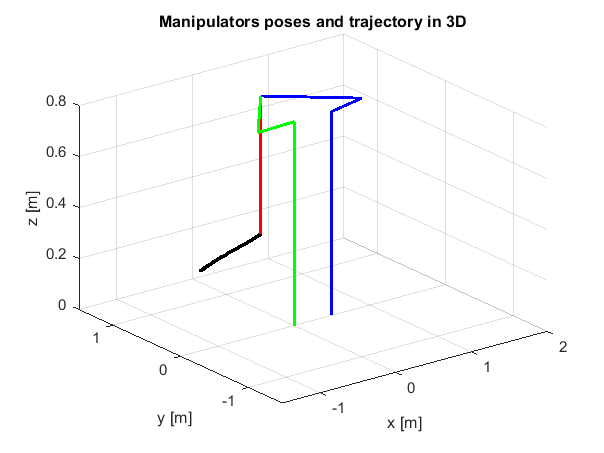

close all
figure(2)
plot3(0,0,0,'LineWidth',4,'color','red') 
xlim([-l1-l2,l0+l1+l2]);
ylim([-l1-l2,l1+l2]);
zlim([0,h]);
xlabel('x [m]')
ylabel('y [m]')
zlabel('z [m]')
title('Manipulators poses and trajectory in 3D');
grid on
for i=1:length(s)
    % Print
    [config1, theta(i)] = Plot3D_1st(q(i,:),L,2,s(i,1),s(i,2));
    [config2, gamma(i)] = Plot3D_2nd(q(i,:),L,2,s(i,1),s(i,2));
    config3 = Plot3D_3rd(L,2,s(i,1),s(i,2),s(i,3));
    plot3(s(i,1),s(i,2),s(i,3),'.-black');
    
    pause(dT)
    if i==length(s)
        break
    end
    delete(config1); delete(config2); delete(config3)
end
hold off

### 1a) Print $\alpha ,\beta ,\gamma \;$and $\theta$

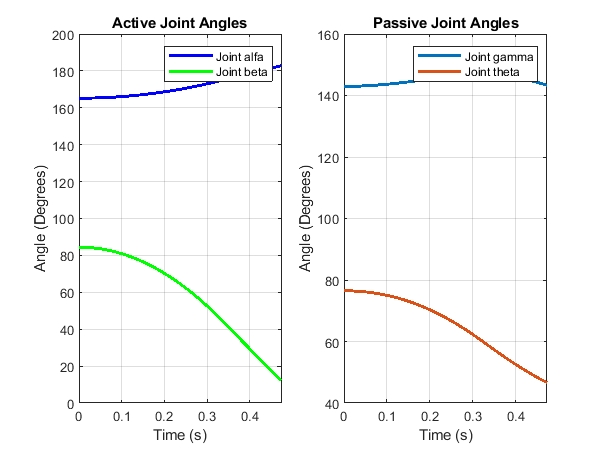

figure(4)
% alpha e beta
subplot(1,2,1)
plot(tt,q(:,1)*180/pi,'b','LineWidth',2);
hold on
plot(tt,q(:,2)*180/pi,'g','LineWidth',2);
hold off
title('Active Joint Angles')
xlabel('Time (s)')
ylabel('Angle (Degrees)')
grid on
legend('Joint alfa','Joint beta')

% gamma e theta
subplot(1,2,2)
plot(tt,gamma*180/pi,'LineWidth',2);
hold on
plot(tt,theta*180/pi,'LineWidth',2);
hold off
title('Passive Joint Angles')
xlabel('Time (s)')
ylabel('Angle (Degrees)')
grid on
legend('Joint gamma','Joint theta')

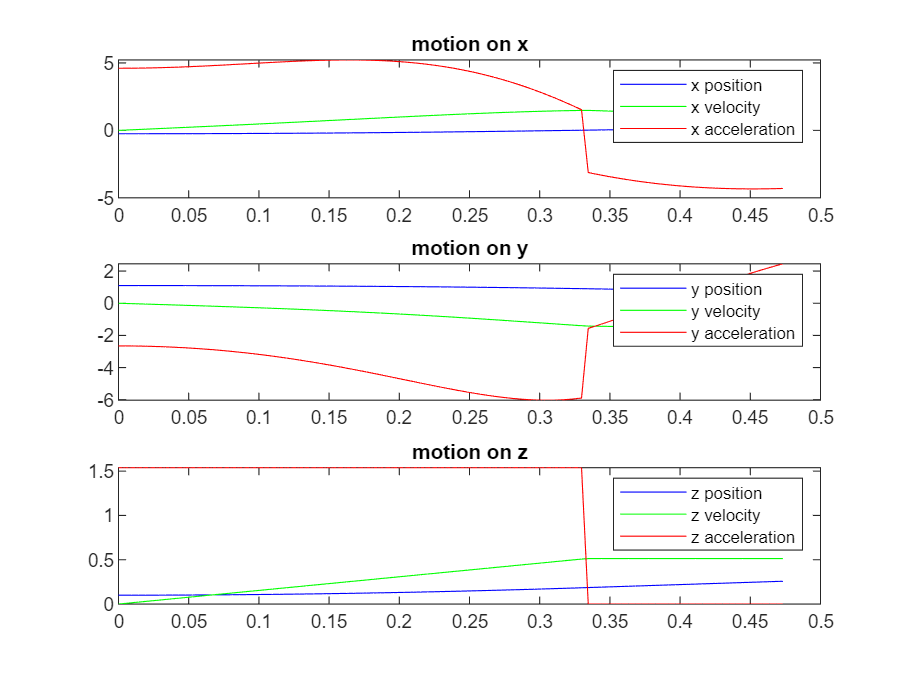

figure(5)
subplot(3,1,1)
plot(tt,s(:,1),'blue',tt,v(:,1),'green',tt,a(:,1),'red')
title('motion on x')
legend('x position','x velocity','x acceleration')
subplot(3,1,2)
plot(tt,s(:,2),'blue',tt,v(:,2),'green',tt,a(:,2),'red')
title('motion on y')
legend('y position','y velocity','y acceleration')
subplot(3,1,3)
plot(tt,s(:,3),'blue',tt,qp(:,3),'green',tt,qpp(:,3),'red')
title('motion on z')
legend('z position','z velocity','z acceleration')

### 1b) Debug

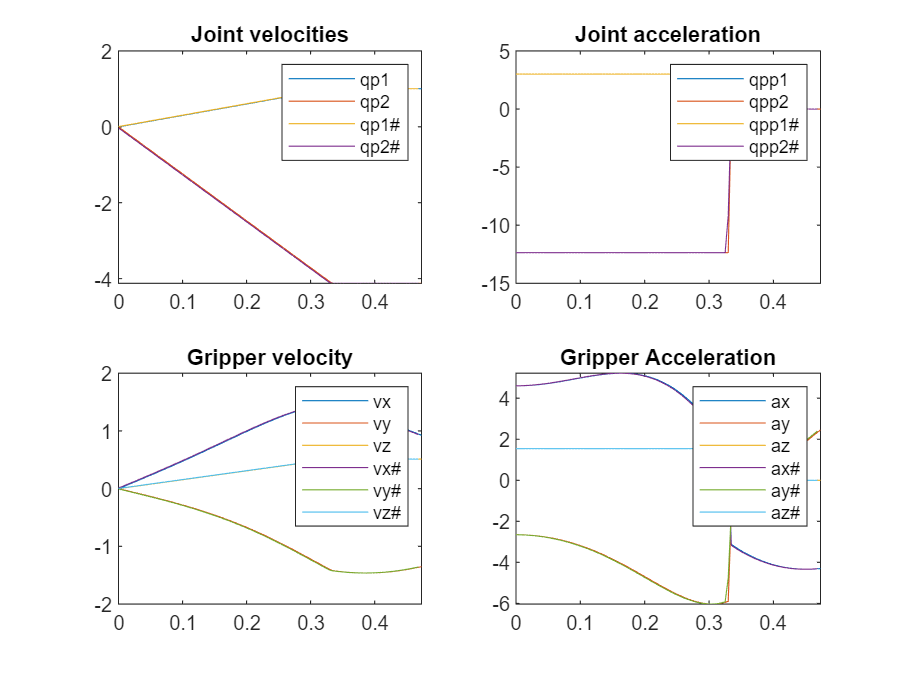

figure(6)
qp_alfa_debug = diff(q(:,1))/dT;
qp_beta_debug = diff(q(:,2))/dT;
qpp_alfa_debug = diff(qp(:,1))/dT;
qpp_beta_debug = diff(qp(:,2))/dT;

subplot(2,2,1)
plot(tt,qp(:,1),tt,qp(:,2),tt(1:end-1),qp_alfa_debug,tt(1:end-1),qp_beta_debug);
legend('qp1','qp2','qp1#','qp2#');
title('Joint velocities')
subplot(2,2,2)
plot(tt,qpp(:,1),tt,qpp(:,2),tt(1:end-1),qpp_alfa_debug,tt(1:end-1),qpp_beta_debug);
legend('qpp1','qpp2','qpp1#','qpp2#')
title('Joint acceleration')

v_x_debug = diff(s(:,1))/dT;
v_y_debug = diff(s(:,2))/dT;
v_z_debug = diff(q(:,3))/dT;
a_x_debug = diff(v(:,1))/dT;
a_y_debug = diff(v(:,2))/dT;
a_z_debug = diff(qp(:,3))/dT;

subplot(2,2,3)
plot(tt,v(:,1),tt,v(:,2),tt,qp(:,3),tt(1:end-1),v_x_debug,tt(1:end-1),v_y_debug,tt(1:end-1),v_z_debug)
legend('vx','vy','vz','vx#','vy#','vz#');
title("Gripper velocity")

subplot(2,2,4)
plot(tt,a(:,1),tt,a(:,2),tt,qpp(:,3),tt(1:end-1),a_x_debug,tt(1:end-1),a_y_debug,tt(1:end-1),a_z_debug)
legend('ax','ay','az','ax#','ay#','az#')
title('Gripper Acceleration')